# Lab - Numerical Differentiation

**Topics: **analytical differentiation using MATLAB, forward, backward and centered finite difference formulas, Richardson extrapolation for differentiation

## Set up system

clear, clc

$D=\frac{d}{\textrm{dx}}\left(\frac{1}{x\;\ln \;x}\right)$, $x=3$

f = @(x) 1./(x.*log(x));
x_i = 3;

## **Analytical differentiation**

syms x
F(x) = 1/(x*log(x));
dF = diff(F)

$$dF(x) = -\frac{1}{x^{2}\,\log\left(x\right)}-\frac{1}{x^{2}\,{\log\left(x\right)}^{2}}$$

df_exact = double(dF(3))

df_exact = -0.1932


PRTE = @(estimate) (df_exact - estimate)...
    ./df_exact*100;

## O(h^2) centered finite-difference, coarse h=0.5

h = 0.5;
x_iplus1 = x_i + h;
x_iminus1 = x_i - h;

df_centered_coarse = (f(x_iplus1)-f(x_iminus1))/(2*h)

df_centered_coarse = -0.2085

PRTE_centered = PRTE(df_centered_coarse)

PRTE_centered = -7.9081

## O(h^2) centered finite-difference, fine h=0.25

h = .25;
x_iplus1 = x_i + h;
x_iminus1 = x_i - h;

df_centered_fine = (f(x_iplus1)-f(x_iminus1))/(2*h)

df_centered_fine = -0.1968

PRTE_centered = PRTE(df_centered_fine)

PRTE_centered = -1.8778

## Richardson extrapolation


$$D=\frac{4}{3}D\left(h_2 \right)-\frac{1}{3}D\left(h_1 \right)$$


df_richard = 4/3*df_centered_fine-1/3*df_centered_coarse

df_richard = -0.1929

PRTE_richard = PRTE(df_richard)

PRTE_richard = 0.1324

## Results display

Headings = ["Method", "Order", "h", "Derivative", "PRTE"];
Methods = ["Analytical", "Centered", ...
    "Centered", "Richardson"];
Orders = ["N/A", "O(h^2)", "O(h^2)", "O(h^4)"];
Steps = ["N/A", "0.5", "0.25", "N/A"];
ders = [df_exact, df_centered_coarse, ...
    df_centered_fine, df_richard];
PRTEs = PRTE(ders);

for line = 1:length(Methods)
    if line == 1
        fprintf('%10s %6s %4s %10s %6s\n', Headings)
        fprintf('---------- ------ ---- ---------- ------\n')
    end
    fprintf('%10s %6s %4s %10.7f %5.1f%%\n', ...
Methods(line), Orders(line), ...
Steps(line), ders(line), PRTEs(line))
    
end

    Method  Order    h Derivative   PRTE


---------- ------ ---- ---------- ------


Analytical    N/A  N/A -0.1931972  -0.0%
  Centered O(h^2)  0.5 -0.2084754  -7.9%
  Centered O(h^2) 0.25 -0.1968250  -1.9%
Richardson O(h^4)  N/A -0.1929415   0.1%


## MATLAB functions

Plot the analytical solution against the numerical solutions found using `gradient `and `diff` for 20 points between x = 2 and 4 

f = @(x) 1./(x.*log(x));

syms x
F(x) = 1/(x*log(x));
dF = diff(F)

$$dF(x) = -\frac{1}{x^{2}\,\log\left(x\right)}-\frac{1}{x^{2}\,{\log\left(x\right)}^{2}}$$

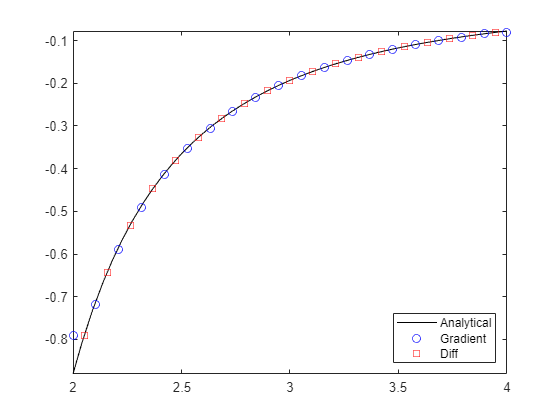


x = linspace(2, 4, 20);
y = f(x);

df_grad = gradient(y,x);
df_diff = diff(y)./diff(x);
x_diff = (x(1:end-1)+x(2:end))/2;

figure()
fplot(dF, [2,4], "-k")
hold on
plot(x, df_grad,"bo", x_diff, df_diff, "rs")
legend("Analytical", "Gradient", "Diff", "location", "southeast")
hold off